# Create Maps From Images

Copyright 2021, The MathWorks, Inc

This script show how to process an image to create an occupancy map representation that can be used for simulation and path planning of autonomous systems. For more information visit the [documentation for Binary Occupancy Maps.](https://www.mathworks.com/help/robotics/ref/binaryoccupancymap.html)

### Load Image with Map Features

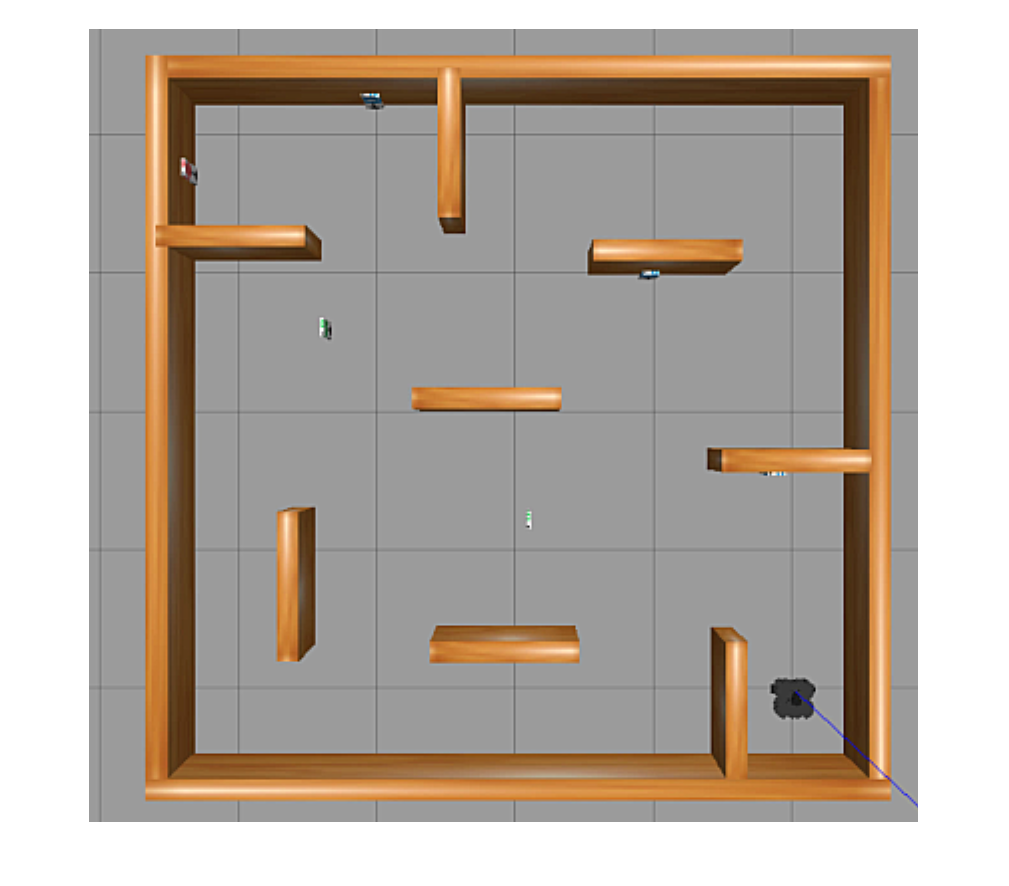

topView = imread('SignFollowerMap_TopImage.PNG');
imshow(topView)

### Threshold Image By Color and Resize

We used the "Color Thresholder" MATLAB® application to create the "createImageMask" function used. For detailed steps to threshold an image by color [see this video](https://www.youtube.com/watch?v=HHpmRjQAiRs&ab_channel=MATLAB).

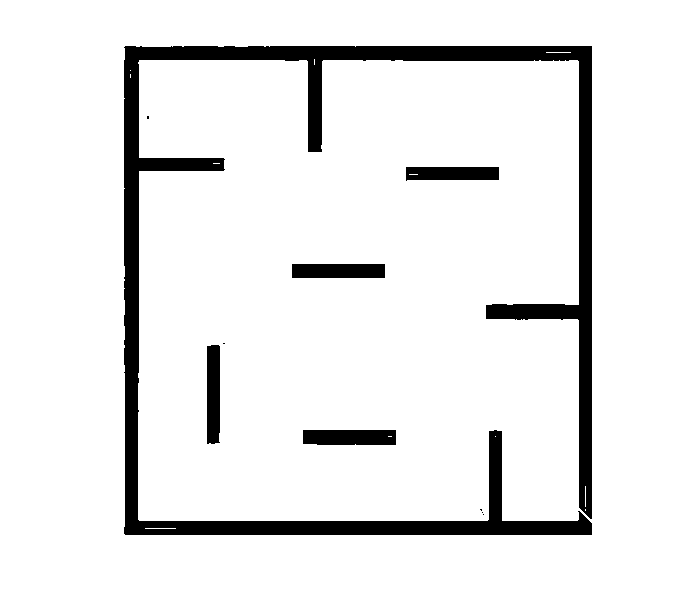

imageMask = createImageMask(topView);
imageMaskResized = imresize(imageMask,[520 520]);
imshow(imageMaskResized)

### Create Occupancy Map and Set Occupied Space

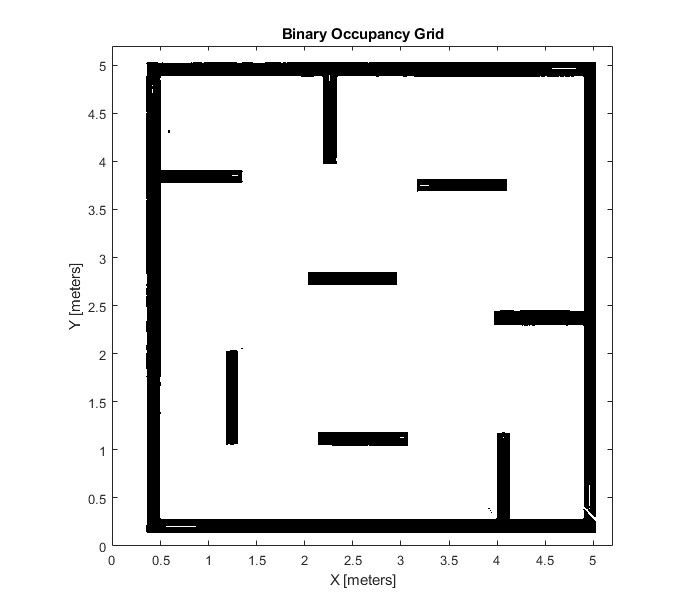

signFollowerMap = binaryOccupancyMap(5.2,5.2,100);
setOccupancy(signFollowerMap,[1 1],~imageMaskResized,"grid")
show(signFollowerMap)